## HIL Testing of Microgrid Energy Management System

## Description

This reference application demonstrates how to perform model-in-the-loop (MIL) and hardware-in-the-loop (HIL) simulation of a grid-connected/islanded microgrid. The model in this example comprises a medium voltage (MV) microgrid with a battery energy storage system, a photovoltaic solar park (PV), loads, as well as an energy management system (EMS) supervisory logic integrating peak shaving control. The microgrid can operate both autonomously (in islanded mode) or in synchronization with the main grid.

### **Learn how to**

- Model and simulate grid-connected and islanded microgrids with renewables and utility-scale energy storage systems

- Design and test EMS supervisory logic and peak shaving controls for various operational scenarios to ensure compliance with grid codes

- Seamlessly transition from MIL to HIL within Simulink without changing your model 

- Configure a PROFINET fieldbus interface between the microgrid digital twin and the EMS controller hardware

- Leverage HIL testing to validate EMS hardware using a digital twin of the microgrid 

## **Supported Model-Based Design Use Cases **

This example supports the following simulation modes (see image below):

- Desktop MIL: Both the microgrid plant and EMS controller run on the development computer. Use this simulation mode to test and verify the EMS logic and microgrid plant design in closed-loop desktop simulation.

- Real-time MIL: Both the microgrid plant and EMS controller run in real-time on a Speedgoat HIL test system to validate real-time aspects. The development computer is used to control the simulation, fine-tune plant and controller parameters, and measure and record real-time data.

- HIL: Reuse the model to generate Structured Text from the EMS logic and deploy it onto a SIEMENS PLC controller. Extend the microgrid plant with fieldbus I/O such as PROFINET. Validate EMS logic and fieldbus communication in real-time by interfacing the PLC controller against the Speedgoat HIL test system.

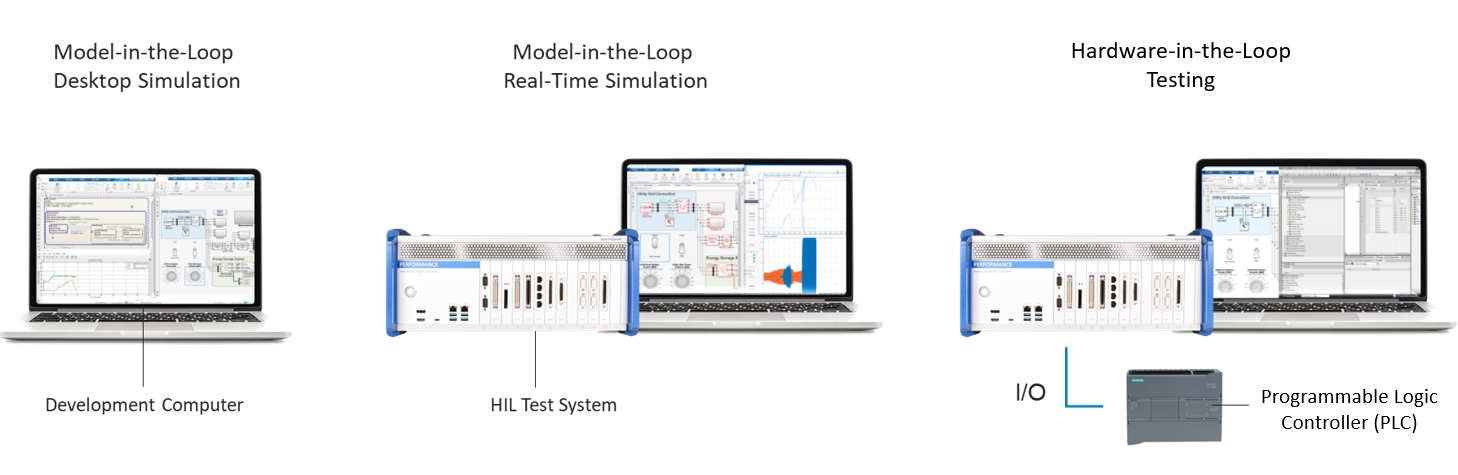

## System Requirements

###     MathWorks Products

-     [Simulink Real-Time™](https://www.mathworks.com/products/simulink-real-time.html)

-     [Simscape™](https://www.mathworks.com/products/simscape.html)

-     [Simscape Electrical™](https://www.mathworks.com/products/simscape-electrical.html)

###     Speedgoat products

-     [Performance Real-Time Target Machine | Speedgoat](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)

-     [IO752: PROFINET Device protocol communication from Simulink](https://www.speedgoat.com/products/communication-protocols-profinet-io752)

## Testbench Configuration

### **    Configure testbench for model-in-the-loop simulation**

mdl = 'microgrid_ESS';
open_system(mdl);
switchConfig(mdl,'MIL'); 

### **    Configure testbench for hardware-in-the-loop testing **

mdl = 'microgrid_ESS';
open_system(mdl);
switchConfig(mdl,'HIL'); 

#### **    Set up PLC Controller**

            1.This project has been set up to work with two different Siemens PLC models: S7-1211C and S7-1214C.  The configuration files for those two PLCs are stored in designated folders separately.  Locate the EMS PLC project file (‘PLC_Peakshaving.ap17’) for the Siemens PLC that you will use within project folder (1211C or 1214C).  The following scripts helps to locate the folder (user to pick the PLC model #)

p = slproject.getCurrentProject;
projectRoot = p.RootFolder;
supportFilesFolder = fullfile(projectRoot,'support_files\source_files\PLC1211C\TIA_Portal'); %for S7-1211C PLC
% supportFilesFolder = fullfile(projectRoot,'support_files\source_files\PLC1214C\TIA_Portal'); %for S7-1214C PLC
eval(['cd ' supportFilesFolder]);

            2. Open and build PLC project in Siemens TIA Portal (V17).  The project file is 'PLC_Peakshaving.ap17’.

    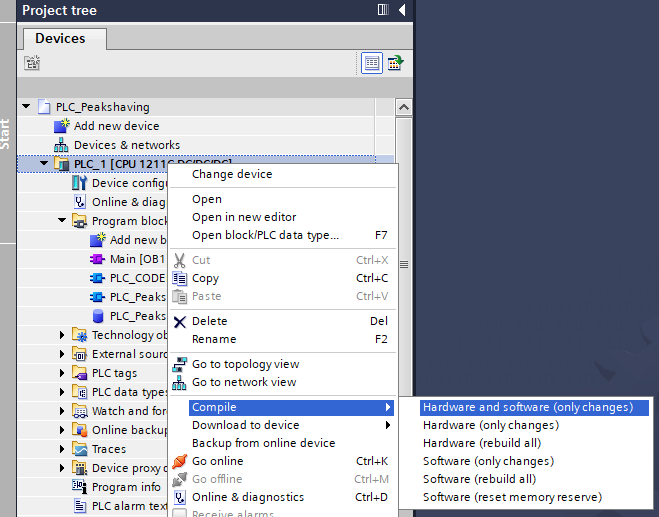

            3. Download compiled project to PLC and "Go Online"

    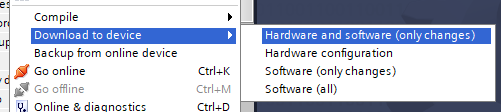

At this stage, the PLC is running and waiting for the HIL test system to trigger its execution.

Note: It is possible to generate Structured Text for different PLC devices using either the EMS controller source model - 'PLC_Peakshaving.slx' -or the generated Structured Text file - 'PLC_Peakshaving.scl'.

#### **    Set up HIL Test System**

mdl = 'microgrid_ESS'
open_system(mdl);
switchConfig(mdl,'HIL');

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download configuration of the IO752 PROFINET Device I/O Module to the target machine
loadconfig;

% Build the Simulink model
slbuild(mdl);   
  
% Download and install the real-time application on the target machine
tg.load(mdl);
  
% Start simulation of real-time application
tg.start;

Note: User may need to modify the Speedgoat PROFINET IO752 card slot number in the IO setup block.  The slot information can be found with the command.

speedgoat.showInstalledIoModules;

Please ensure that you enter the slot information in the IO752 setup block as shown in the picture below.

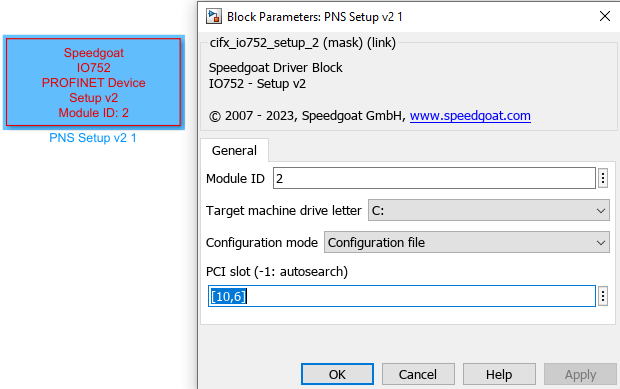

**    PLC- HIL Test System Connectitivy Settings**

The example uses the following IP addresses for the development computer,  PLC, and Speedgoat HIL simulator:

- Development computer: 172.21.200.30

- Speedgoat HIL test system: 172.21.200.1

- PLC: 172.21.200.16

## **Exercises**

### **    Exercise 1: ****Peak Shaving Control**

Users are encouraged to exercise this in both MIL and HIL.  

In grid-tied mode, the load power is sourced from three different sources: the grid, solar panels, and the battery. The user has the flexibility to determine the amount of power to be supplied from the battery by adjusting the 'Additional Battery Supply [MW]' parameter on the graphical user interface (GUI). The remaining power required is then sourced from both the grid and the solar panel.

To manage power distribution effectively, the user can define a power threshold known as the 'Utility Max Power Setpoint [MW]'. When the combined power from the grid and the battery exceeds this threshold, the grid power will be limited, and the battery will compensate for the power deficit. This control mechanism is referred to as peak shaving.

The first chart below illustrates the scenario where the 'Additional Battery Supply [MW]' is set to zero, indicating that the battery is solely utilized for peak shaving purposes, and the peak shaving level is 1 MW.

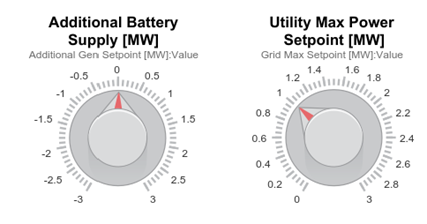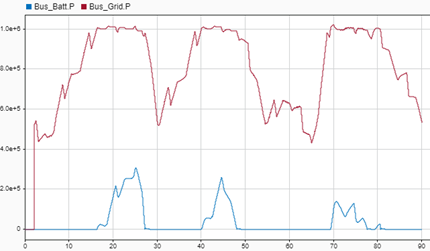

The second chart illustrates the scenario where the battery power setpoint is set to 0.2 MW, and the peak shaving threshold is set to 0.8 MW. In this configuration, when the combined power from the battery and the grid exceeds 0.8 MW, the grid power will be constrained to 0.6 MW. The additional power required to meet the total load, including the promised 0.2 MW from the battery, will be sourced from the battery.

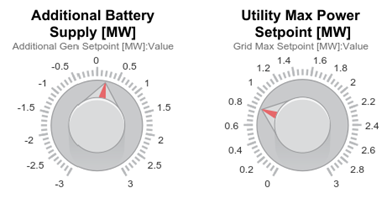  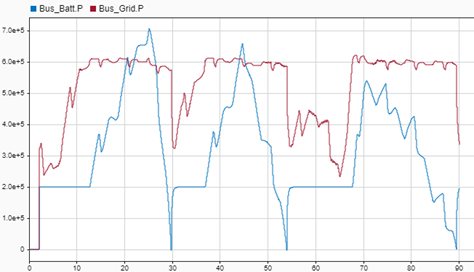

The battery can also operate in charging mode by setting the 'Additional Battery Supply [MW]' parameter with a negative value. In the following example, the battery is requesting a charging rate of -0.2 MW, and the 'Utility Max Power Setpoint [MW]' is set to 0.8 MW. As a result, when the peak shaving control is active, the grid power will be limited to 1 MW.

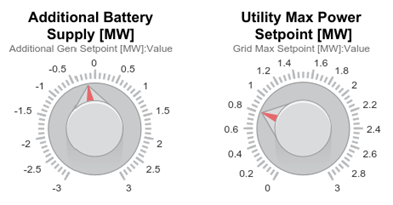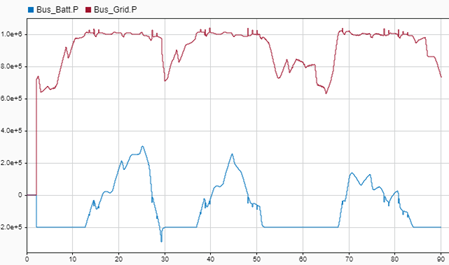

For detailed information about the peak shaving algorithm, including the ‘LoadFollowing’ and ‘MaxLocalGeneration’ functionalities during peak shaving, users can access the Stateflow chart inside the MIL block. This Stateflow chart provides detailed insights into the inner workings of the peak shaving algorithm.

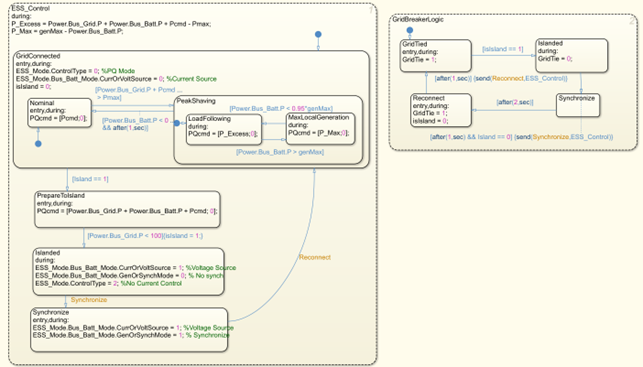

### **    Exercise 2: **Assessing the Impact of Solar Power Generation (Weather) on Peak Shaving Control

Weather conditions have a significant impact on solar power generation. By switching from the 'Clear' weather setting to 'Cloudy', for example, the solar power output is reduced from approximately 0.45 MW to around 0.02 MW. When running the simulation again under these weather conditions, it becomes evident that the grid needs to compensate for the power loss from the decreased solar generation. As a result, peak shaving events occur more frequently during cloudy days compared to sunny days.

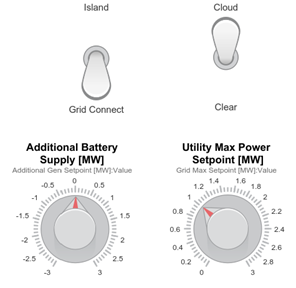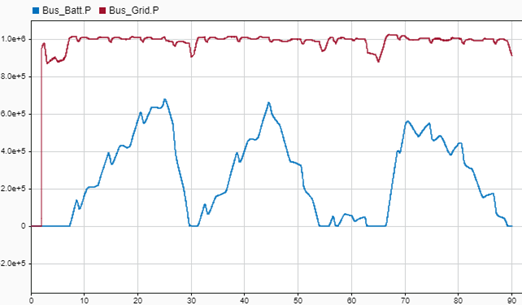

### **    Exercise 3: Exploring Island Mode and Transitions**

During the Island mode, the microgrid operates independently with no connection to the main grid, relying solely on the power generated by the solar panels and the battery. In this mode, the battery plays a crucial role by supplying additional power, causing a faster depletion of its state of charge (SOC). Users can also observe the transitions into and out of the island mode, which occur approximately at T20 seconds (when transitioning into island mode) and T70 seconds (when returning to grid-tied mode).

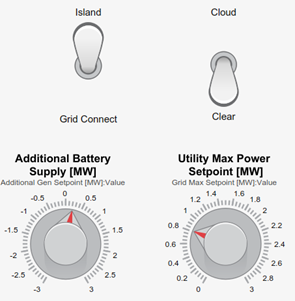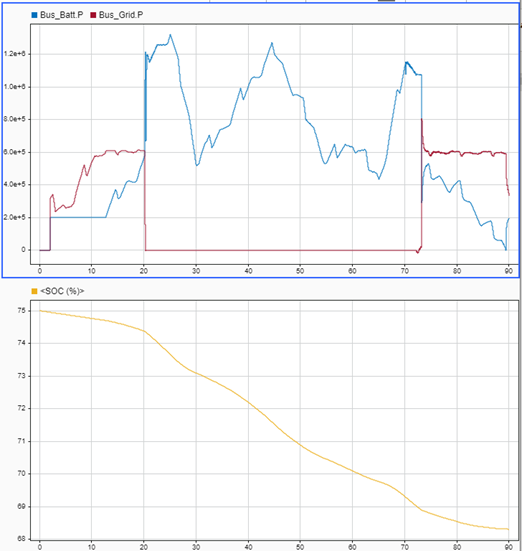

## Related Content

- [Microgrids and Renewables | Speedgoat](https://www.speedgoat.com/solutions/industries/power-systems/microgrids-and-renewables)

- [Protocol Support for Microgrid HIL](http://content.speedgoat.com/products-services/communications-protocols/industrial-automation)

- [HIL Testing for Microgrids | Webinar | Speedgoat](https://www.speedgoat.com/knowledge-center/webinars/hardware-in-the-loop-testing-for-microgrids) 

- [Microgrid System Development and Analysis - MATLAB & Simulink (mathworks.com)](https://ch.mathworks.com/videos/series/microgrid-system-development-and-analysis.html)

## Release Notes

open README.md